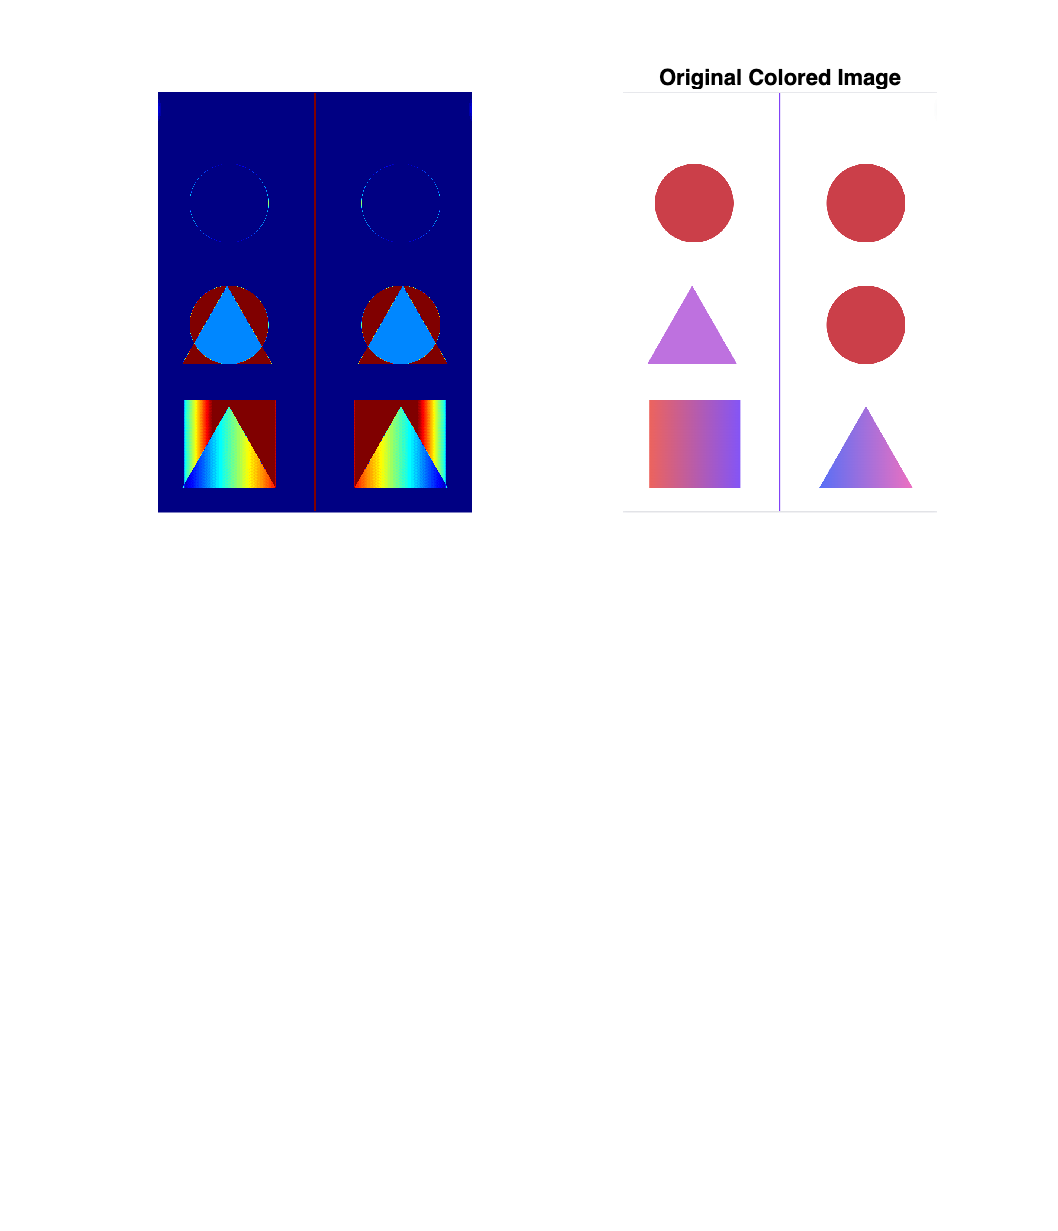

I = imread("raw_images/shapes.png");

% splitting color channels
I_red = I(:,:,1);
I_green = I(:,:,2);
I_blue = I(:,:,3);

flippedImage = fliplr(I_red); % flip img


imshow(I);
title("Original Colored Image")

disp(size(I)); % size displ.

        1132         844           3



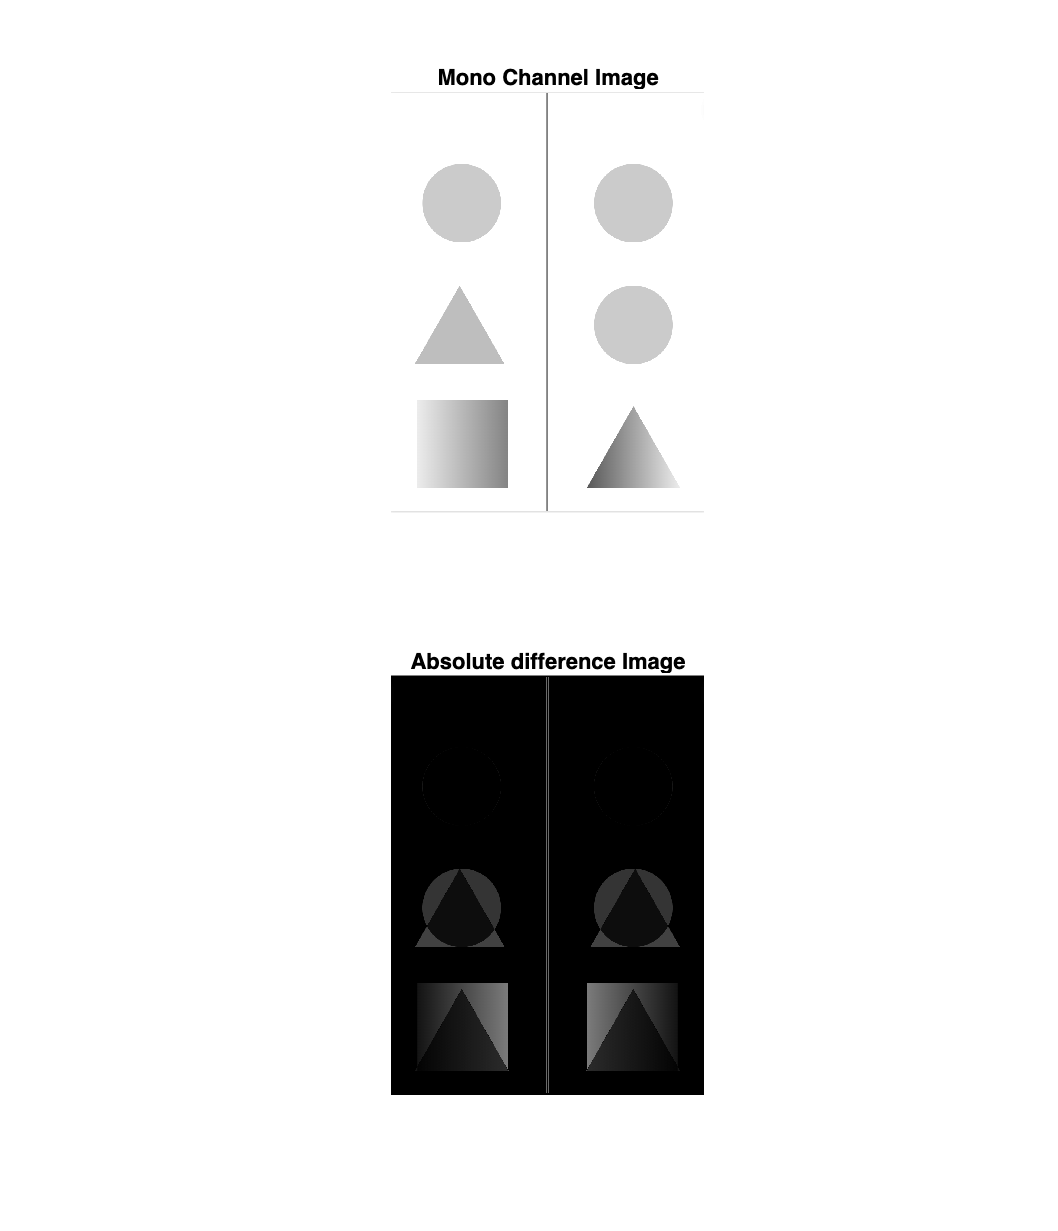

subplot(2, 1, 1);
imshow(I_red);
title("Mono Channel Image")

difference = double(I_red) - double(flippedImage); 
% the difference function is not working properly, 
% use k = double(i)-double(j); to convert the img to double format to perform subtraction that will give you negative value.


% final image -> Absolute difference Image
subplot(2, 1, 2);
laterality_of_image = uint8(abs(difference)); % convert the img back to uint8 from double.
imshow((laterality_of_image));
title("Absolute difference Image");



% the Absolute difference Image checks the laterality of th eimage in one
% color channel.

% Now, for the same color channel of the original image 'varible = I_red' (i.e red color channel), we use a
% different color (GREEN) to represent the intensity of the image in the red
% color channel. 

intensity_of_image = I_red;

% blue channel should be the array of same size as the original image but
% with all matrix values as 0.
blueChannel = I_red; % we take a mono_channel from the original Image and then set its values to 0. 
% In this case we're I_red but it doesn't really matters.


% setting up channels
redChannel = laterality_of_image; % red -> laterality 
greenChannel = intensity_of_image; % green -> intensity
blueChannel = zeros(size(blueChannel));

#### Convert RGB to HSV

We're taking our original image and converting it to HSV.

We keep the hue and value same but change the saturation by mono- channel of intensity.

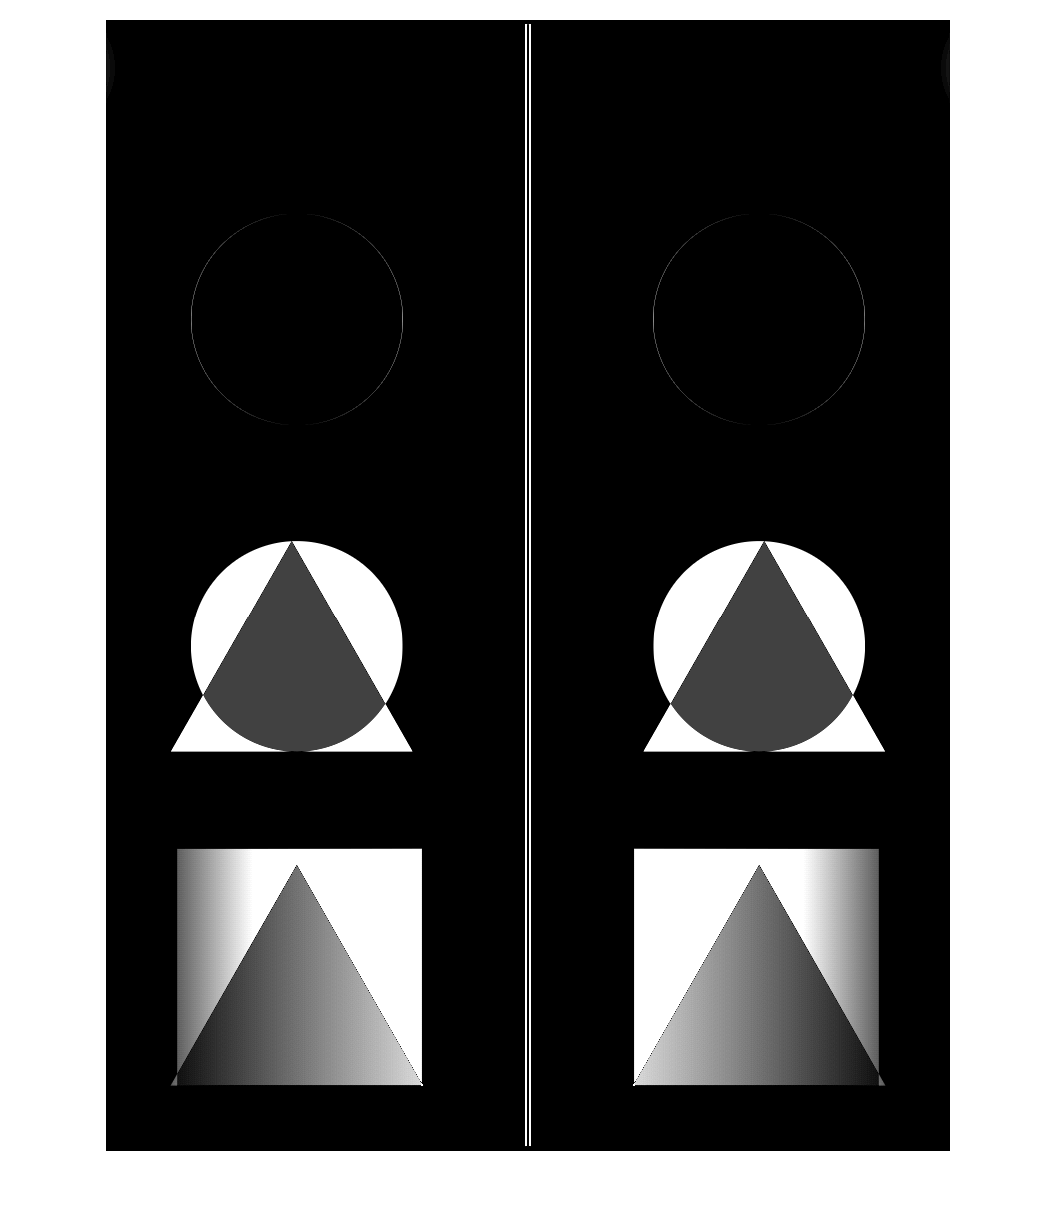

%adjust the contrast
% contrast_adjusted_gray_img = imadjust(laterality_of_image, [0 1], [0 1]);
contrast_adjusted_gray_img = laterality_of_image * 5;

cmap = jet(256); % Use the 'jet' colormap with 256 levels
pseudocoloredImage = ind2rgb(contrast_adjusted_gray_img, cmap);
figure();
imshow(contrast_adjusted_gray_img);

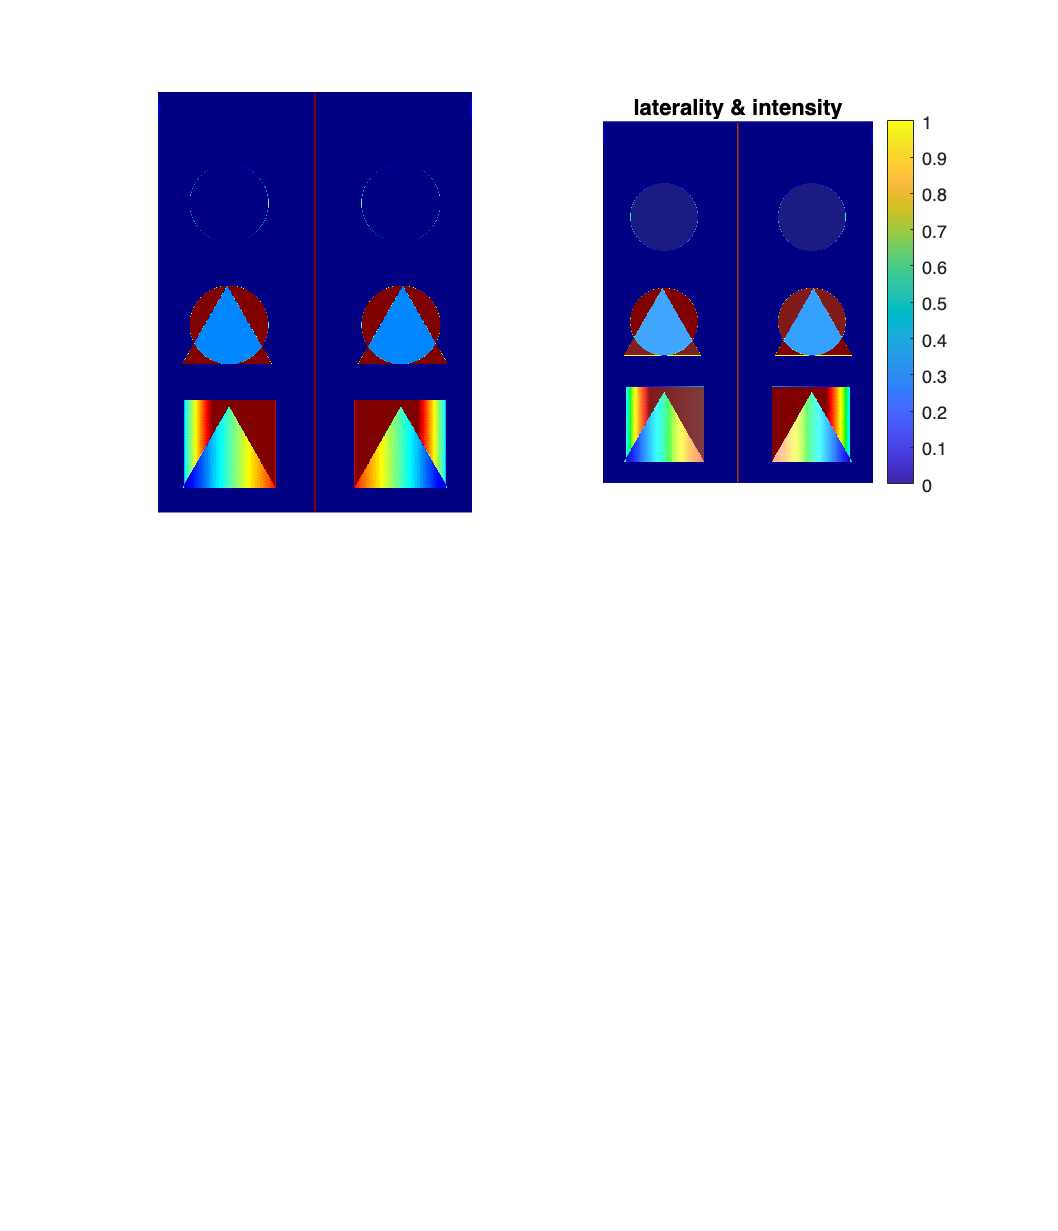

Error using matlab.graphics.illustration.ColorBar/set
Unable to set the 'Label' property of class 'ColorBar' because it is read-only.

Error in colorbar (line 251)
    set(cbar,pvpairs{:});

% convert the RGB img to HSL (HSL will look weird in the display bc the
% regular monitors use RGB to do color representation.)
hsv_img = rgb2hsv(pseudocoloredImage);
[H, S, V] = imsplit(hsv_img);
S = double(double(intensity_of_image)/255);
% V(:) = 5;
LIC = cat(3,H,S,V);
Product_img = hsv2rgb(LIC);

subplot(2, 2, 1)
imshow(pseudocoloredImage);

subplot(2, 2, 2)
imshow(Product_img);
title("laterality & intensity");
colorbar('Label', 'Color');